load('face_detect_demo.mat')
ana=faces_test_easy(:,:,5);
kai=faces_test_easy(:,:,16);
%someone = faces_test_easy(:,:,26);

M10 = 3.3.*ana + 1.2 .* kai; % + 1.0.*someone;
M20 = 1.1.*ana + 3.2 .*kai; % + 0.8.*someone;
%M30 = 0.2.*ana + 0.3.*kai + 0.8.*someone;

%Reshape training face images into column vectors
M1=reshape(M10,[256^2,1]);
M2 =reshape(M20,[256^2,1]);
%M3 = reshape(M30,[256^2,1]);
M = [M1,M2]';

[Mw, whiteningMatrix, dewhiteningMatrix, means] = preprocessing(M);

[A,W] = icaRounds(whiteningMatrix, dewhiteningMatrix, Mw, means);

icasig = W * M + (W * means) * ones(1, 65536);


unmix1=reshape(icasig(1,:),[256 256]);
unmix2=reshape(icasig(2,:),[256 256]);
%unmix3=reshape(icasig(3,:),[256 256]);

% clc
% subplot(2,3,1)
% imagesc(M10); colormap('gray');
% title('Mix 1')
% 
% subplot(2,3,2)
% imagesc(M20); colormap('gray');
% title('Mix 2')
% 
% subplot(2,3,3)
% imagesc(M30); colormap('gray');
% title('Mix 3')
% 
% subplot(2,3,4)
% imagesc(unmix1); colormap('gray');
% title('Recovered signal 1')
% 
% subplot(2,3,5)
% imagesc(unmix2); colormap('gray');
% title('Recovered signal 2')
% 
% subplot(2,3,6)
% imagesc(unmix3); colormap('gray');
% title('Recovered signal 3')

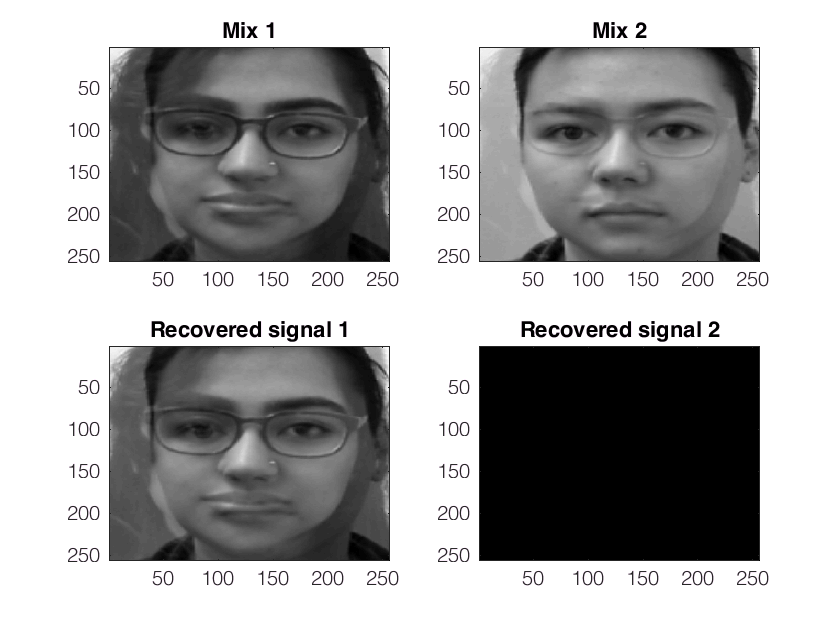

clc
subplot(2,2,1)
imagesc(M10); colormap('gray');
title('Mix 1')

subplot(2,2,2)
imagesc(M20); colormap('gray');
title('Mix 2')

subplot(2,2,3)
imagesc(unmix1); colormap('gray');
title('Recovered signal 1')

subplot(2,2,4)
imagesc(unmix2); colormap('gray');
title('Recovered signal 2')